# Slosh 3D - Rotation about z

ZY Parametrization of the spherical pendulum, with imposed rotation of the container about its z axis

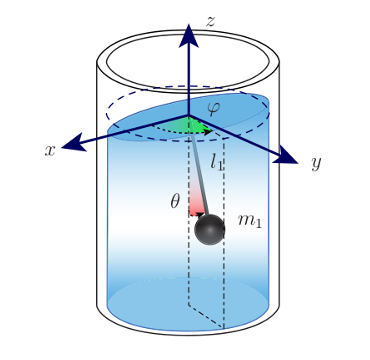

In this code the equation of motion for the pendulum angles representing the sloshing are derived through the use of the Euler-Lagrange equations.

This sloshing model represent the 3D motion of the pivot, but it is the same for any point with a displacement along z of the cylinder axis.

A rotation about the axis of the container is imposed.

clc 
clear all

syms theta(t) phi(t) gamma(t)
syms t 
syms h l m g b d
syms x(t) y(t) z(t) 

$\theta$ = second rotation about Y describing the sloshing

$\phi$ = first rotation abouy Z describing the plane of sloshing

l = length of pendulum

m = mass of pendulum

h = height of the liquid

b = damping coefficient

$\gamma$ = imposed angle of rotation about z

## Derivation of the pendulum coordinates

Through the use of homogeneous transformation matrices infer the position of the pendulum mass and of the liquid mass in the world reference frame. 

Use of the parametrization using 3-2-3 euler angle convention. Note: to have the mass lying in the positive quadrant (x and y positive) the second rotation about y is taken in the opposite direction.

### Homogeneous Transformation from inertial frame to container

% First rotation about z
R_z_gamma = [cos(gamma),  -sin(gamma), 0;
           sin(gamma),   cos(gamma), 0;
           0,          0,        1];

% Second rotation about y
% R_y_beta = [cos(-beta),  0,  sin(-beta);
%               0,            1,            0;
%              -sin(-beta),  0,  cos(-beta)];

R = R_z_gamma%*R_y_beta;

$$R(t) = \left(\begin{array}{ccc} \cos\left(\gamma \left(t\right)\right) & -\sin\left(\gamma \left(t\right)\right) & 0\\ \sin\left(\gamma \left(t\right)\right) & \cos\left(\gamma \left(t\right)\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

Define translation vector

% p = [0; 0; 0];
p = [x(t); y(t); z(t)];

Define the transformation

T_wc = [R, p; 0 0 0 1];
T_wc = formula(T_wc);

% Display the transformation matrix
disp('Homogeneous Transformation Matrix from world to container:');

Homogeneous Transformation Matrix from world to container:


disp(T_wc);

$$\left(\begin{array}{cccc} \cos\left(\gamma \left(t\right)\right) & -\sin\left(\gamma \left(t\right)\right) & 0 & x\left(t\right)\\ \sin\left(\gamma \left(t\right)\right) & \cos\left(\gamma \left(t\right)\right) & 0 & y\left(t\right)\\ 0 & 0 & 1 & z\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Homogeneous Transformation from container to pivot

% First rotation about z
R_z_phi = [cos(phi),  -sin(phi), 0;
           sin(phi),   cos(phi), 0;
           0,          0,        1];

% Second rotation about y
R_y_theta = [cos(-theta),  0,  sin(-theta);
              0,            1,            0;
             -sin(-theta),  0,  cos(-theta)];

% Third rotation about z
R_z_phi_minus = [cos(-phi),  -sin(-phi), 0;
               sin(-phi),   cos(-phi), 0;
               0,          0,        1];

R = R_z_phi * R_y_theta %* R_z_phi_minus

$$R(t) = \left(\begin{array}{ccc} \cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right) & -\sin\left(\varphi \left(t\right)\right) & -\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\\ \cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right) & \cos\left(\varphi \left(t\right)\right) & -\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\\ \sin\left(\theta \left(t\right)\right) & 0 & \cos\left(\theta \left(t\right)\right) \end{array}\right)$$

Define translation vector

p = [0; 0; 0];
% p = [x(t); y(t); z(t)];

Define the transformation

T_cp = [R, p; 0 0 0 1];
T_cp = formula(T_cp);

% Display the transformation matrix
disp('Homogeneous Transformation Matrix from container to pivot:');

Homogeneous Transformation Matrix from container to pivot:


disp(T_cp);

$$\left(\begin{array}{cccc} \cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right) & -\sin\left(\varphi \left(t\right)\right) & -\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right) & 0\\ \cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right) & \cos\left(\varphi \left(t\right)\right) & -\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right) & 0\\ \sin\left(\theta \left(t\right)\right) & 0 & \cos\left(\theta \left(t\right)\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


$$p_m =$$

$$\left(\begin{array}{c}
l\,\cos \left(\phi \left(t\right)\right)\,\sin \left(\theta \left(t\right)\right)\\
l\,\sin \left(\phi \left(t\right)\right)\sin \left(\theta \left(t\right)\right)\\
-l\,\cos \left(\theta \left(t\right)\right)
\end{array}\right)$$


### Homogeneous Transformation from pivot to mass

Define translation vector

p = [0; 0; -l];

Homogeneous transformation

T_pm = [eye(3), p; 0 0 0 1];
T_pm = formula(T_pm);

% Display the transformation matrix
disp('Homogeneous Transformation Matrix from pivot to mass:');

Homogeneous Transformation Matrix from pivot to mass:


disp(T_pm);

$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & -l\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Pendulum mass coordinates in inertial frame

Derive the homogeneous transformation from inertial frame to pendulum mass.

T_wm = T_wc*T_cp*T_pm;

Derive the coordinates of the pendulum mass

xm = T_wm(1,4)

$$xm = x\left(t\right)+l\,\left(\cos\left(\gamma \left(t\right)\right)\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)-\sin\left(\gamma \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\right)$$

ym = T_wm(2,4)

$$ym = y\left(t\right)+l\,\left(\cos\left(\gamma \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)+\cos\left(\varphi \left(t\right)\right)\,\sin\left(\gamma \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\right)$$

zm = T_wm(3,4)

$$zm = z\left(t\right)-l\,\cos\left(\theta \left(t\right)\right)$$


$$x_m =\;x\left(t\right)+l\,\cos \left(\phi \left(t\right)\right)\,\sin \left(\theta \left(t\right)\right)$$



$$y_{m\;} =\;y\left(t\right)+l\,\sin \left(\phi \left(t\right)\right)\sin \left(\theta \left(t\right)\right)$$



$$z_m =\;z\left(t\right)-l\,\cos \left(\theta \left(t\right)\right)$$


Coordinates of pendulum mass relative to the pivot

xr = l*cos(phi)*sin(theta)

$$xr(t) = l\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)$$

yr = l*sin(phi)*sin(theta)

$$yr(t) = l\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)$$

zr = -l*cos(theta)

$$zr(t) = -l\,\cos\left(\theta \left(t\right)\right)$$

## Derivation of the equations of motion

Derive the equation of motion finding kinetic and potential energies and then assembling the lagrangian equation with respect to theta.

### Kinetic Energy

xm_dot = diff(xm, t);
ym_dot = diff(ym, t);
zm_dot = diff(zm, t);

xr_dot = diff(xr, t);
yr_dot = diff(yr, t);
zr_dot = diff(zr, t);

#### Kinetic energy for the pendulum

Sum the contributions of the kinetic energies in x, y and z

Tmx = 0.5 * m * xm_dot^2;
Tmx = simplify(Tmx)

$$Tmx = \frac{m\,{\left(l\,\cos\left(\gamma \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\gamma \left(t\right)-l\,\cos\left(\gamma \left(t\right)\right)\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)-\frac{\partial }{\partial t}x\left(t\right)+l\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\gamma \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\gamma \left(t\right)+l\,\cos\left(\gamma \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)+l\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\gamma \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)+l\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\gamma \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}$$

%disp(latex(Tmx))

Tmy = 0.5 * m * ym_dot^2;
Tmy = simplify(Tmy)

$$Tmy = \frac{m\,{\left(\frac{\partial }{\partial t}y\left(t\right)+l\,\cos\left(\gamma \left(t\right)\right)\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\gamma \left(t\right)+l\,\cos\left(\gamma \left(t\right)\right)\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)+l\,\cos\left(\gamma \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)+l\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\gamma \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)-l\,\sin\left(\gamma \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\gamma \left(t\right)-l\,\sin\left(\gamma \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}}{2}$$

%disp(latex(Tmx))

Tmz = 0.5 * m * zm_dot^2;
Tmz = simplify(Tmz)

$$Tmz = \frac{m\,{\left(\frac{\partial }{\partial t}z\left(t\right)+l\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}$$

%disp(latex(Tmz))

Tm = Tmx + Tmy + Tmz

T = Tm;


$$\frac{m\,{{\left(\frac{\partial }{\partial t}\mathrm{\ }y\left(t\right)+l\,\cos \left(\gamma \left(t\right)\right)\,\cos \left(\phi \left(t\right)\right)\,\sin \left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\gamma \left(t\right)+l\,\cos \left(\gamma \left(t\right)\right)\,\cos \left(\phi \left(t\right)\right)\,\sin \left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\phi \left(t\right)+l\,\cos \left(\gamma \left(t\right)\right)\,\cos \left(\theta \left(t\right)\right)\,\sin \left(\phi \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\theta \left(t\right)+l\,\cos \left(\phi \left(t\right)\right)\,\cos \left(\theta \left(t\right)\right)\,\sin \left(\gamma \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\theta \left(t\right)-l\,\sin \left(\gamma \left(t\right)\right)\,\sin \left(\phi \left(t\right)\right)\,\sin \left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\gamma \left(t\right)-l\,\sin \left(\gamma \left(t\right)\right)\,\sin \left(\phi \left(t\right)\right)\,\sin \left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\phi \left(t\right)\right)}}^2 }{2}+\frac{m\,{{\left(\frac{\partial }{\partial t}\mathrm{\ }z\left(t\right)+l\,\sin \left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\theta \left(t\right)\right)}}^2 }{2}+\frac{m\,{{\left(-\frac{\partial }{\partial t}\mathrm{\ }x\left(t\right)-l\,\cos \left(\gamma \left(t\right)\right)\,\cos \left(\phi \left(t\right)\right)\,\cos \left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\theta \left(t\right)+l\,\cos \left(\gamma \left(t\right)\right)\,\sin \left(\phi \left(t\right)\right)\,\sin \left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\gamma \left(t\right)+l\,\cos \left(\phi \left(t\right)\right)\,\sin \left(\gamma \left(t\right)\right)\,\sin \left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\gamma \left(t\right)+l\,\cos \left(\gamma \left(t\right)\right)\,\sin \left(\phi \left(t\right)\right)\,\sin \left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\phi \left(t\right)+l\,\cos \left(\phi \left(t\right)\right)\,\sin \left(\gamma \left(t\right)\right)\,\sin \left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\phi \left(t\right)+l\,\cos \left(\theta \left(t\right)\right)\,\sin \left(\gamma \left(t\right)\right)\,\sin \left(\phi \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\theta \left(t\right)\right)}}^2 }{2}$$


### Potential energy

%% Potential energy
Um = m * g * zm;

U = Um;
U = simplify(U);
disp("Potential energy:");

Potential energy:


disp(U);

$$g\,m\,\left(z\left(t\right)-l\,\cos\left(\theta \left(t\right)\right)\right)$$


$$U=g\,m\,{\left(z\left(t\right)-l\,\cos \left(\theta \left(t\right)\right)\right)}$$


### Rayleigh function

To account for dissipied energy

theta_dot = diff(theta, t);
phi_dot = diff(phi, t);

v2 = xr_dot^2 + yr_dot^2+ zr_dot^2

$$v2(t) = {\left(l\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)+l\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+{\left(l\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)-l\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}+l^{2}\,{\sin\left(\theta \left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}$$


D = b/2 *(v2);

D_dthetadot = diff(D, theta_dot);
D_dphidot = diff(D, phi_dot);

### Lagrangian

%% Lagrangian 
L = T - U;
L = simplify(L)


% wrt theta
L_thetadot = diff(L, diff(theta(t), t));
L_thetadot = simplify(L_thetadot);

dL_theta_dot = diff(L_thetadot, t);
dL_theta_dot = simplify(dL_theta_dot);

L_theta = diff(L, theta(t));
L_theta = simplify(L_theta)


% wrt phi
L_phi_dot = diff(L, diff(phi(t), t));
L_phi_dot = simplify(L_phi_dot);

dL_phi_dot = diff(L_phi_dot, t);
dL_phi_dot = simplify(dL_phi_dot);

L_phi = diff(L, phi(t));
L_phi = simplify(L_phi);

### Equation of motion

#### Theta

%for theta, that represents the swing of the pendulum and, accordingly, the sloshing dynamics.
eqn_theta = dL_theta_dot - L_theta + D_dthetadot;
% eqn_theta = eqn_theta + b * diff(theta, t);
eqn_theta = simplify(eqn_theta);
disp("Equation of motion with respect to theta:");

Equation of motion with respect to theta:


disp(eqn_theta);

$$b\,l^{2}\,\frac{\partial }{\partial t}\theta \left(t\right)+l^{2}\,m\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)-\frac{l^{2}\,m\,\sin\left(2\,\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\gamma \left(t\right)\right)}^{2}}{2}-\frac{l^{2}\,m\,\sin\left(2\,\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}}{2}+l\,m\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}z\left(t\right)+g\,l\,m\,\sin\left(\theta \left(t\right)\right)-l^{2}\,m\,\sin\left(2\,\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)\,\frac{\partial }{\partial t}\gamma \left(t\right)+l\,m\,\cos\left(\gamma \left(t\right)\right)\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+l\,m\,\cos\left(\gamma \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+l\,m\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\gamma \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)-l\,m\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\gamma \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)$$

disp("Latex Equation of motion with respect to theta:");

Latex Equation of motion with respect to theta:


disp(latex(eqn_theta));

b\,l^2\,\frac{\partial }{\partial t} \theta \left(t\right)+l^2\,m\,\frac{\partial ^2}{\partial t^2} \theta \left(t\right)-\frac{l^2\,m\,\sin\left(2\,\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t} \Gamma \left(t\right)\right)}^2}{2}-\frac{l^2\,m\,\sin\left(2\,\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t} \phi \left(t\right)\right)}^2}{2}+l\,m\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} z\left(t\right)+g\,l\,m\,\sin\left(\theta \left(t\right)\right)-l^2\,m\,\sin\left(2\,\theta \left(t\right)\right)\,\frac{\partial }{\partial t} \phi \left(t\right)\,\frac{\partial }{\partial t} \Gamma \left(t\right)+l\,m\,\cos\left(\Gamma \left(t\right)\right)\,\cos\left(\phi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} x\left(t\right)+l\,m\,\cos\left(\Gamma \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\phi \left(t\right)\right)\,\frac{\partial ^2}{\partial t^

Simplify notation 

syms c_theta s_theta c_phi s_phi c_gamma s_gamma
syms theta_dot theta_ddot phi_dot phi_ddot x_ddot y_ddot z_ddot gamma_dot gamma_ddot
eq_sub1 = subs(eqn_theta,[cos(theta(t)), sin(theta(t)), cos(phi(t)),sin(phi(t)), cos(gamma(t)),sin(gamma(t))],[c_theta s_theta c_phi s_phi c_gamma s_gamma]);
eq_sub2 = subs(eq_sub1, [diff(diff(theta(t),t),t),diff(diff(phi(t),t),t),diff(diff(x(t),t),t),diff(diff(y(t),t),t),diff(diff(z(t),t),t), diff(diff(gamma(t),t),t)],[theta_ddot,phi_ddot,x_ddot,y_ddot,z_ddot, gamma_ddot]);
eq_sub3 = subs(eq_sub2, [diff(theta(t),t),diff(phi(t),t),diff(gamma(t),t)],[theta_dot,phi_dot,gamma_dot]);
eq_sub3 = simplify(eq_sub3);

% eqn1 = isolate(eqn_theta == 0, diff(theta(t),t,t));
eqn1 = isolate(eq_sub3 == 0, theta_ddot);
eqn1 = collect(eqn1, [x_ddot, y_ddot, z_ddot, g, gamma_dot^2, gamma_ddot, phi_dot^2, phi_ddot, theta_dot]);
disp(eqn1);

$$\ddot{\theta }=\left(-\frac{c_{\gamma }\,c_{\varphi }\,c_{\theta }\,l\,m-c_{\theta }\,l\,m\,s_{\gamma }\,s_{\varphi }}{l^{2}\,m}\right)\,\ddot{x}+\left(-\frac{c_{\gamma }\,c_{\theta }\,l\,m\,s_{\varphi }+c_{\varphi }\,c_{\theta }\,l\,m\,s_{\gamma }}{l^{2}\,m}\right)\,\ddot{y}+\left(-\frac{s_{\theta }}{l}\right)\,\ddot{z}+\left(-\frac{s_{\theta }}{l}\right)\,g+\frac{\sin\left(2\,\theta \left(t\right)\right)}{2}\,{\dot{\gamma }}^{2}+\frac{\sin\left(2\,\theta \left(t\right)\right)}{2}\,{\dot{\varphi }}^{2}+\left(-\frac{b}{m}\right)\,\dot{\theta }+\dot{\gamma }\,\dot{\varphi }\,\sin\left(2\,\theta \left(t\right)\right)$$

disp(latex(eqn1));

\ddot{\theta }=\left(-\frac{c_{\gamma }\,c_{\phi }\,c_{\theta }\,l\,m-c_{\theta }\,l\,m\,s_{\gamma }\,s_{\phi }}{l^2\,m}\right)\,\ddot{x}+\left(-\frac{c_{\gamma }\,c_{\theta }\,l\,m\,s_{\phi }+c_{\phi }\,c_{\theta }\,l\,m\,s_{\gamma }}{l^2\,m}\right)\,\ddot{y}+\left(-\frac{s_{\theta }}{l}\right)\,\ddot{z}+\left(-\frac{s_{\theta }}{l}\right)\,g+\frac{\sin\left(2\,\theta \left(t\right)\right)}{2}\,{\dot{\gamma }}^2+\frac{\sin\left(2\,\theta \left(t\right)\right)}{2}\,{\dot{\phi }}^2+\left(-\frac{b}{m}\right)\,\dot{\theta }+\dot{\gamma }\,\dot{\phi }\,\sin\left(2\,\theta \left(t\right)\right)



$$\ddot{\theta} =-\frac{b}{m}\,\dot{\theta} +{\left(-\frac{c_{\theta } \,\cos \left(\gamma +\phi \right)}{l}\right)}\,\ddot{x} +{\left(-\frac{c_{\theta } \;\sin \left(\gamma +\phi \right)}{l}\right)}\,\ddot{y} +{\left(-\frac{s_{\theta } }{l}\right)}\,\left(\ddot{z} +g\right)+\,c_{\theta } \;s_{\theta } \left({\dot{\gamma} }^2 +{\dot{\phi} }^2 \right)+2\dot{\gamma} \,\dot{\phi} \,c_{\theta } \;s_{\theta }$$


Which can be rewritten as:


$$\ddot{\theta} =-\frac{b}{m}\,\dot{\theta} -\frac{1}{l_n }c_{\theta \;} \left(\cos \left(\gamma +\phi \right)\;\ddot{x} \;+\;\sin \left(\gamma +\phi \right)\ddot{\;y} \right)-\frac{1}{l_n }s_{\theta } \,\left(\ddot{z} +g\right)+\,c_{\theta } \;s_{\theta } {\left(\dot{\gamma} +\dot{\phi} \right)}^2$$


#### Phi

%for phi
eqn_phi = dL_phi_dot - L_phi + D_dphidot;
% eqn_phi = eqn_phi + b * diff(phi, t);
eqn_phi = simplify(eqn_phi);
disp("Equation of motion with respect to phi:");

Equation of motion with respect to phi:


disp(eqn_phi);

$$l\,\sin\left(\theta \left(t\right)\right)\,\left(m\,\cos\left(\gamma \left(t\right)+\varphi \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)-m\,\sin\left(\gamma \left(t\right)+\varphi \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+b\,l\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)+l\,m\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\gamma \left(t\right)+l\,m\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\varphi \left(t\right)+2\,l\,m\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)+2\,l\,m\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\gamma \left(t\right)\right)$$

disp("Latex Equation of motion with respect to phi:");

Latex Equation of motion with respect to phi:


disp(latex(eqn_phi));

l\,\sin\left(\theta \left(t\right)\right)\,\left(m\,\cos\left(\Gamma \left(t\right)+\phi \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} y\left(t\right)-m\,\sin\left(\Gamma \left(t\right)+\phi \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} x\left(t\right)+b\,l\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t} \phi \left(t\right)+l\,m\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} \Gamma \left(t\right)+l\,m\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} \phi \left(t\right)+2\,l\,m\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t} \theta \left(t\right)\,\frac{\partial }{\partial t} \phi \left(t\right)+2\,l\,m\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t} \theta \left(t\right)\,\frac{\partial }{\partial t} \Gamma \left(t\right)\right)



syms c_theta s_theta c_phi s_phi c_gamma s_gamma
syms theta_dot theta_ddot phi_dot phi_ddot x_ddot y_ddot z_ddot gamma_dot gamma_ddot
eq_sub1 = subs(eqn_phi,[cos(theta(t)), sin(theta(t)), cos(phi(t)),sin(phi(t)), cos(gamma(t)),sin(gamma(t))],[c_theta s_theta c_phi s_phi c_gamma s_gamma]);
eq_sub2 = subs(eq_sub1, [diff(diff(theta(t),t),t),diff(diff(phi(t),t),t),diff(diff(x(t),t),t),diff(diff(y(t),t),t),diff(diff(z(t),t),t), diff(diff(gamma(t),t),t)],[theta_ddot,phi_ddot,x_ddot,y_ddot,z_ddot, gamma_ddot]);
eq_sub3 = subs(eq_sub2, [diff(theta(t),t),diff(phi(t),t),diff(gamma(t),t)],[theta_dot,phi_dot,gamma_dot]);
eq_sub3 = simplify(eq_sub3);

% eqn2 = isolate(eqn_phi == 0, diff(phi(t),t,t));
eqn2 = isolate(eq_sub3 == 0, phi_ddot);
eqn2 = collect(eqn2, [x_ddot, y_ddot, z_ddot, g, gamma_dot^2, gamma_ddot, phi_dot^2, phi_ddot, theta_dot]);

disp(eqn2);

$$\ddot{\varphi }=\frac{\sin\left(\gamma \left(t\right)+\varphi \left(t\right)\right)}{l\,s_{\theta }}\,\ddot{x}+\left(-\frac{\cos\left(\gamma \left(t\right)+\varphi \left(t\right)\right)}{l\,s_{\theta }}\right)\,\ddot{y}-\ddot{\gamma }+\left(-\frac{2\,c_{\theta }\,\dot{\gamma }\,l\,m+2\,c_{\theta }\,l\,m\,\dot{\varphi }}{l\,m\,s_{\theta }}\right)\,\dot{\theta }-\frac{b\,\dot{\varphi }}{m}$$

disp(latex(eqn2));

\ddot{\phi }=\frac{\sin\left(\Gamma \left(t\right)+\phi \left(t\right)\right)}{l\,s_{\theta }}\,\ddot{x}+\left(-\frac{\cos\left(\Gamma \left(t\right)+\phi \left(t\right)\right)}{l\,s_{\theta }}\right)\,\ddot{y}-\ddot{\gamma }+\left(-\frac{2\,c_{\theta }\,\dot{\gamma }\,l\,m+2\,c_{\theta }\,l\,m\,\dot{\phi }}{l\,m\,s_{\theta }}\right)\,\dot{\theta }-\frac{b\,\dot{\phi }}{m}



$$\ddot{\phi} =-\frac{b\,\dot{\phi} }{m}-\ddot{\gamma} +\frac{\sin \left(\gamma +\phi \right)}{l\,s_{\theta } }\,\ddot{x} +{\left(-\frac{\cos \left(\gamma +\phi \right)}{l\,s_{\theta } }\right)}\,\ddot{y} +{\left(-\frac{2\,c_{\theta } \,\left(\dot{\gamma} +\dot{\phi} \right)}{\,s_{\theta } }\right)}\,\dot{\theta}$$


Which can be seen as:


$$s_{\theta } \,\ddot{\phi} =-s_{\theta } \,\ddot{\gamma} -\frac{b\,}{m}\dot{\phi} \,s_{\theta } +\frac{1}{l_n }\left(\sin \left(\gamma +\phi \right)\,\ddot{x} -\,\cos \left(\gamma +\phi \right)\,\ddot{y} \right)-2\,c_{\theta } \,\left(\dot{\gamma} +\dot{\phi} \right)\;\dot{\theta} \;$$


# Algebraic compensation of Sloshing

Given that the desired sloshing wanted is null, the angle $\theta$ and its derivatives are assumed null. The equations become:

- 
$$0=\sin \left(\gamma +\phi \right)\,\ddot{x} -\,\cos \left(\gamma +\phi \right)\,\ddot{y}$$


- 
$$0=c_{\theta \;} \left(\cos \left(\gamma +\phi \right)\;\ddot{x} \;+\;\sin \left(\gamma +\phi \right)\ddot{\;y} \right)+s_{\theta } \,\left(\ddot{z} +g\right)$$


From which we can derive:

- 
$$\frac{\ddot{y} }{\ddot{x} }=\tan \left(\gamma +\phi \right)$$


- 
$$\tan \left(\theta \right)\;=-\frac{\cos \left(\gamma +\phi \right)\;\ddot{x} \;+\;\sin \left(\gamma +\phi \right)\ddot{\;y} }{\ddot{z} +g}$$


Finally:

- 
$$\phi =-\gamma +\;\textrm{atan2}\left(\ddot{y} \;,\,\ddot{x} \;\right)$$


- 
$$\theta =\tan^{-1} \left(-\frac{\cos \left(\gamma +\phi \right)\;\ddot{x} \;+\;\sin \left(\gamma +\phi \right)\ddot{\;y} }{\ddot{z} +g}\right)$$


Conveniently, substituting eq. (1) into (2) gives:


$$\theta =\tan^{-1} \left(-\frac{\cos \left(\textrm{atan2}\left(\ddot{y} \;,\,\ddot{x} \;\right)\right)\;\ddot{x} \;+\;\sin \left(\textrm{atan2}\left(\ddot{y} \;,\,\ddot{x} \;\right)\right)\ddot{\;y} }{\ddot{z} +g}\right)$$


Knowing that:


$$\cos \left(\tan^{-1} \frac{\ddot{y} }{\ddot{x} }\right)=\frac{\ddot{x} }{\sqrt{{\ddot{y} }^2 +{\ddot{x} }^2 }}$$



$$\sin \left(\tan^{-1} \frac{\ddot{y} }{\ddot{x} }\right)=\frac{\ddot{y} }{\sqrt{{\ddot{y} }^2 +{\ddot{x} }^2 }}$$


It follows that the numerator becomes 

$\cos \left(\textrm{atan2}\left(\ddot{y} \;,\,\ddot{x} \;\right)\right)\;\ddot{x} \;+\;\sin \left(\textrm{atan2}\left(\ddot{y} \;,\,\ddot{x} \;\right)\right)\ddot{\;y}$ = $\frac{\ddot{x} }{\sqrt{{\ddot{y} }^2 +{\ddot{x} }^2 }}+\frac{\ddot{y} }{\sqrt{{\ddot{y} }^2 +{\ddot{x} }^2 }}=\frac{{\ddot{y} }^2 +{\ddot{x} }^2 }{\sqrt{{\ddot{y} }^2 +{\ddot{x} }^2 }}=\sqrt{{\ddot{x} }^2 +{\ddot{y} }^2 }\;$

and so:


$$\theta =\tan^{-1} \left(-\frac{\sqrt{{\ddot{x} }^2 +{\ddot{y} }^2 }}{\ddot{z} +g}\right)$$


More conveniently, if we take 


$$\phi =\pi -\gamma +\;\textrm{atan2}\left(\ddot{y} \;,\,\ddot{x} \;\right)$$


$\theta$ becomes:


$$\theta =\tan^{-1} \left(-\frac{-\cos \left(\textrm{atan2}\left(\ddot{y} \;,\,\ddot{x} \;\right)\right)\;\ddot{x} \;-\sin \left(\textrm{atan2}\left(\ddot{y} \;,\,\ddot{x} \;\right)\right)\ddot{\;y} }{\ddot{z} +g}\right)$$


   
$$=\tan^{-1} \left(\frac{\sqrt{{\ddot{x} }^2 +{\ddot{y} }^2 }}{\ddot{z} +g}\right)$$
